# Elaborato MatLab - Approssimazione e Interpolazione dati

## Introduzione alle Spline

Consideriamo un intervallo [a, b], all'interno del quale andiamo a prendere una successione finita di numeri reali, che chiameremo **nodi**, tali che godano tutti del seguente ordinamento:


$$a=x_0 <x_1 <x_2 <\;\ldotp \ldotp \ldotp <x_N =b$$


Nel caso di una interpolazione di tipo polinomiale, si è visto che presi i valori $y_0 ,\ldotp \ldotp \ldotp y_N$ assunti dalla funzione $y=f\left(x\right)$ nei punti considerati, esiste un unico polinomio di grado N tale che:


$$p_N \left(x_i \right)=f_i \;,\;i=0,\ldotp \ldotp \ldotp ,N$$


Tramite una sequenza di punti scelti con l'ordine precedente, sto identificando una partizione dell'intervallo [a, b] in *N* sottointervalli, ognuno dei quali è possibile indicare in questo modo:


$$I_i =\left\lbrack x_i \;,x_{i+1} \right\rbrack \;\forall \;i=0,\ldotp \ldotp \ldotp ,N$$


Nel caso di nodi che sono equispaziati, cioè del tipo


$$x_k =a+k\;\frac{\left(b-a\right)}{N}\;,k=0,\ldotp \ldotp \ldotp ,N;$$


al crescere del valore di N, e cioè all'aumentare del numero di nodi, non posso garantire che la differenza $f\left(x\right)-p_N \left(x\right)$ tenda a zero, per il **teorema di Runge**.

Più in generale però, per il **teorema di Faber**, per ogni insieme di nodi considerato, relativo all'intervallo [a, b], esisterà una funzione continua $f$ tale che l'interpolante ad essa associata $P_n$ non converga uniformemente alla funzione nei punti considerati, per $n\to \infty$. In altre parole, non vale che al tendere di $n\to +\infty$


$$\lim_{N\to \infty } \;\max_{x\in \left\lbrack a,b\right\rbrack }^{\;} \;\left|f\left(x\right)\;-P_N \left(x\right)\right|\to 0$$


Quindi un problema è quello di trovare un polinomio approssimante che sia valido per un numero elevato di punti, anche equispaziati, e che converga alla funzione $f$ che sto considerando.

Nel 1946 Schoenberg da una risposta al problema posto, scoprendo le **spline. **

## **Le spline**

Si definisce **Spline **di grado *n (*o di ordine *n+1)* relativa ad una partizione ${\left\lbrace x_i \right\rbrace }_{i=0}^{m+1}$ dell'intervallo [a, b] considerato, una funzione *s(x) *che soddisfa le seguenti proprietà:

- $s\left(x\right)$ è un polinomio $s_i \left(x\right)$di grado non superiore a *n* in ciascun sottointervallo $I_i$della partizione che ho considerato

- $s\left(x\right)\in C^{n-1} \left(\left\lbrack a,b\right\rbrack \right)$, ossia la funzione e le sue derivate sono continue sull'intervallo [a, b] che sto considerando

Considerando la seconda proprietà, significa che per ogni nodo interno alla partizione effettuata, vale la seguente condizione:


$$s_i^{\left(k\right)} \left(x_{i+1} \right)=s_{i+1}^{\left(k\right)} \left(x_{i+1} \right)\;,i=0,\ldotp \ldotp \ldotp ,m-1,k=0,\ldotp \ldotp \ldotp ,n-1$$


In altre parole, una spline *s(x)* negli intervalli $I_i$ è un polinomio di grado al più *n*, che in ogni punto interno all'intervallo la funzione è $C^{\infty }$ e agli estremi coincide con il polinomio relativo all'intervallo precedente e successivo (se essi esistono) fino alla derivata *(n-1)*esima.

### Spline di grado 1

Il grado della spline definisce quindi l'andamento della funzione s(x) che attraversa l'intervallo di punti che ho definito. Maggiore è il grado della spline, meno la curva è "spigolosa"; infatti una spline di grado **1** è sostanzialmente una spezzata che unisce i nodi che ho considerato, come vediamo nella figura generabile tramite il codice in basso.

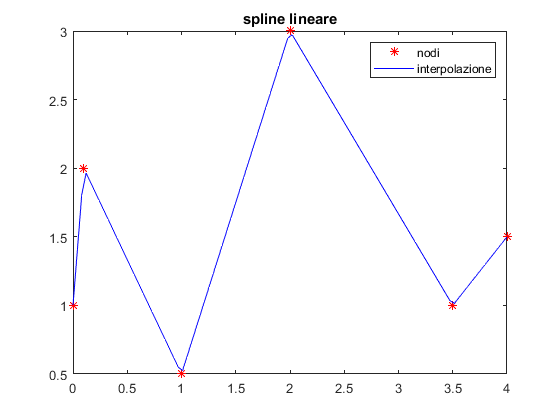

x = [0 0.1 1 2 3.5 4];
y = [1 2 0.5 3 1 1.5];
t = linspace(0,4);
pt = interp1(x,y,t);
plot(x,y,'* red',t, pt, 'b-')
legend({'nodi','interpolazione'})
title('spline lineare');

### Spline di grado 3

Un modo quindi per fare si che la curva spline sia più dolce è aumentare il grado della spline stessa. Una delle spline più utilizzare è la **spline di grado 3**, detta anche **spline cubica**, dal grado del polinomio che viene generato.

Le spline cubiche sono spesso utilizzate per effettuare delle interpolazioni di alcuni dati in ingresso. Infatti, dati dei punti $\left(x_i \;,y_i \right),i=0,\ldotp \ldotp \ldotp ,m+1$ ciò che voglio è una spline adatta per effettuare l'interpolazione di tali punti, tale che $s\left(x_i \right)=y_i$, con $x_i$ ingresso della spline coincidente con le ascisse dei punti che voglio interpolare.

Generalmente, per fare ciò vengono quindi utilizzate le spline cubiche, perchè godono di una proprietà particolare; infatti, tra tutte le funzioni $f\left(x\right)\in C^2 \left(\left\lbrack a,b\right\rbrack \right)$, che soddisfano la condizione di interpolazione detta in precedenza, e che cioè appartengono allo **spazio di Sobolev**, cioè lo spazio di funzioni a derivate **deboli**, cioè a derivate $L^1$, fino ad un certo ordine, le spline cubiche corrispondenti a tali funzioni sono le uniche in grado di minimizzare il seguente integrale


$$E\left(f\right)=\int_a^b {\left\lbrack f^" \left(x\right)\right\rbrack }^2 \;\textrm{dx}$$


$E\;\left(f\right)$ rappresenta una approssimazione della curvatura totale della funzione $f$ nell'intervallo [a, b]. 

L'integrale deriva dalla storia delle spline stesse: originariamente le *spline* erano degli strumenti da disegno formati da lunghe fettucce elastiche tenute ferme nei punti di interpolazione da dei grossi pesi. Il significato originale della parola inglese *spline* è appunto *striscia di legno o metallo. *Tra i due pesi, ossia tra i punti di interpolazione, la fettuccia poteva essere facilemente modellata tramite l'equazione elastica semplificata:


$$f{{{{\;}^{\prime } }^{\prime } }^{\prime } }^{\prime } \;\left(x\right)=0$$


che da effettivamente origine ad un polinomio di grado 3. La fettuccia si andava quindi a modellare in modo da minimizzare proprio l'integrale, che rappresenta l'energia elastica della fettuccia. Geometricamente si dice che la fettuccia si dispone in modo da minimizzare la curvatura media.

Per una spline di grado 3, l'unicità dell'interpolante è legata all'aggiunta di proprità riguardanti gli estremi $x_0 \;,x_N$. Si può osservare infatti che in ogni intervallo $\left\lbrack x_i \;,x_{i+1} \right\rbrack$ ogni spline cubica è rappresentabile come segue


$$s_3 \;\left(x\right)\;=c_{1,i} +\;c_{2,i} \;\left(x-x_i \right)+c_{3,i} \;{\left(x-x_i \right)}^2 +c_{4,i} \;{\left(x-x_i \right)}^3 \;,i=0,\ldotp \ldotp \ldotp ,N-1$$
 

e che quindi per determinare $s_3 \;$in ogni punto $x_i$ ho bisogno di stabilire 4N valori $c_{i,j}$. In realtà però, ragionando sulla regolarità della spline interpolante, si vede che ho bisogno di 4N - 2 condizioni, di cui N+1 riguardano il valore della spline nei punti $x_i$ . Aggiungendo le due condizioni mancanti andiamo a creare delle spline specifiche:

- ***spline naturale***, se $s_3^{\left(2\right)} \left(a\right)=s_3^{\left(2\right)} \left(b\right)=0$;

- ***spline periodica***, se $s_3^{\left(1\right)} \left(a\right)=s_3^{\left(1\right)} \left(b\right)$ e $s_3^{\left(2\right)} \left(a\right)=s_3^{\left(2\right)} \left(b\right)$;

- ***spline vincolata***, se $s_3^{\left(1\right)} \left(a\right)=f_{\;}^{\left(1\right)} \left(a\right)$ e $s_3^{\left(1\right)} \left(b\right)=f_{\;}^{\left(1\right)} \left(b\right)$.

e altre tipologie di spline, come quella ***not-a-knot ***o quella di ***Hermite***.

Per una spline di tipo ***not-a-knot*** il vincolo impone la continuità della derivata terza della spline nel secondo e nel penultimo nodo dell'insieme che sto considerando. In altre parole, la suddivisione degli intervalli è data dai seguenti sottointervalli:


$$\left\lbrack x_0 \;,x_2 \right\rbrack \;,\left\lbrack x_2 \;,x_3 \right\rbrack ,\ldotp \ldotp \ldotp ,\left\lbrack x_{N-2} \;,x_N \right\rbrack$$


e i dati $y_0 ,\ldotp \ldotp \ldotp ,y_N$ vengono interpolati nei nodi $x_0 ,\ldotp \ldotp \ldotp ,x_N$. Interessante è osservare che, nel caso di una condizione *not-a-knot* si considerano *N-2* intervalli, e il numero di condizioni di cui si necessita per determinare la spline cubica sono *4(N-2),* di cui *N+1* sono dovute all'interpolazione mentre quelle dovute alla regolarità sono *3(N-3)*, poichè ho *N-3* nodi che sono estremi di sottintervalli interni, in particolare i nodi $x_2 ,\ldotp \ldotp \ldotp ,x_{N-2}$.

Vediamo effettivamente come lavora una spline cubica con un set di nodi in ingresso: andiamo a costruire un vettore di nodi con annesso valore delle ascisse e utilizziamo la routine di Matlab per il calcolo della spline interpolante di grado 3:

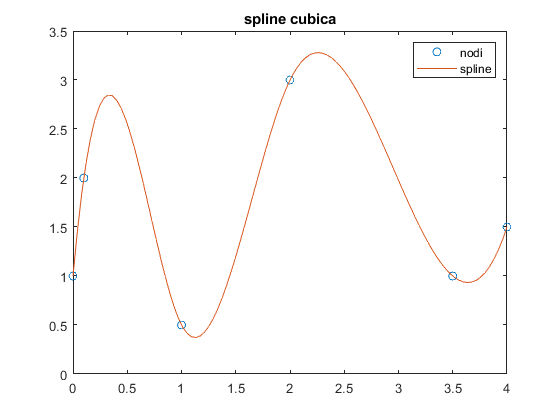

x = [0 0.1 1 2 3.5 4];
y = [1 2 0.5 3 1 1.5];
t = linspace(0,4);
pt = spline(x, y, t); % se non specificato, la spline costruita tramite comando spline, rispetta il vincolo not-a-knot
plot(x, y, 'o', t, pt)

legend({'nodi','spline'})
title('spline cubica')

## Errore dell'interpolante spline

Andiamo ad effetuare uan stima degli errori che conseguono ad una spline interpolante prima lineare e poi cubica. 

### Errore di una Spline di grado 1

Come prima cosa, consideriamo una spline lineare di grado 1 $s_1 :\left\lbrack a,b\right\rbrack \to R$ tale da interpolare le coppie ${\left(x_i \;,f\left(x_i \right)\right)}_{\;}$, dove i nodi $x_i$ sono così ordinati:


$${a\;=\;x}_1 <x_2 <\;\ldotp \ldotp \ldotp <x_i \;<\;x_{i+1} <\;\ldotp \ldotp \ldotp <x_N =\;b$$


Dal **teorema dell'interpolazione polinomiale** abbiamo che, puntualmente vale la seguente relazione


$$f\left(x\right)-p_N \left(x\right)=f^{\left(2\right)} \left(\xi \right)\;\frac{\left(x-x_0 \right)\;\left(x-x_1 \right)}{2}\;,\xi \in \left(a,\;b\right)$$
 

Dalla seguente relazione è immediato ricavare la stima dell'errore uniforme per funzioni che sono di classe $C^2$ nell'intervallo [a, b]; infatti si ottiene che


$$\left|f\left(x\right)-s_1 \left(x\right)\right|\le h_i^2 \;\frac{M_i }{8}$$


dove $h_i =\left(x_{i+1} -x_i \right)\;,i=0,\ldotp \ldotp \ldotp ,N-1$ mentre $M_i =\max_{x\in \left(x_i \;,\;x_{i+1} \right)}^{\;} \;\left|f^{\left(2\right)} \;\left(x\right)\right|$.

Infatti, se $x\in \left\lbrack x_i \;,\;x_{i+1} \right\rbrack$ dall'equazione di interpolazione polinomiale è possibile ricavare che


$$\begin{array}{l}
\left|f\left(x\right)-s_1 \left(x\right)\right|=\left|f^{\left(2\right)} \left(\xi \right)\;\frac{\left(x-x_i \right)\;\left(x-x_{i+1} \right)}{2}\right|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left|f^{\left(2\right)} \left(\xi \right)\right|\left|\;\frac{\left(x-x_i \right)\;\left(x-x_{i+1} \right)}{2}\right|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\le \max_{x\in \left\lbrack x_i \;,\;x_{i+1} \right\rbrack }^{\;} \;\left|f^{\left(2\right)} \;\left(x\right)\right|\cdot \max_{x\in \left\lbrack x_i \;,\;x_{i+1} \right\rbrack }^{\;} \;\left|\;\frac{\left(x-x_i \right)\;\left(x-x_{i+1} \right)}{2}\right|
\end{array}$$


Da qui ottengo l'asserto, dato che il massimo della seconda quantità si ha quando $c=\left(x_i +x_{i+1} \right)\;/\;2$ e quindi posso scrivere che


$$\left|\;\frac{\left(x-x_i \right)\;\left(x-x_{i+1} \right)}{2}\right|\le \left|\;\frac{\left(c-x_i \right)\;\left(c-x_{i+1} \right)}{2}\right|=\frac{1}{2}\;\left|\;\frac{\left(x_{i+1} -x_i \right)\;}{2}\;\frac{\left(x_i -x_{i+1} \right)}{2}\right|=\frac{h_i^2 }{8}\;\ldotp$$


### Errore di una Spline di grado 3

Analizziamo ora l'errore commesso da una spline cubica del tipo $s_1 :\left\lbrack a,b\right\rbrack \to R$ che interpola anch'essa coppie di punti ${\left(x_i \;,f\left(x_i \right)\right)}_{\;}$con i punti ordinati allo stesso modo considerato per una spline di grado 1. E' utile ricordare che se la funzione $f\;:\left\lbrack a,b\right\rbrack \to R$ è continua allore è possibile definirne la norma come segue:

${\left\|f\right\|}_{\infty } \;:=\max_{x\in \left\lbrack a,b\right\rbrack }^{\;} \;\left|f\left(x\right)\right|$.

Per quanto riguarda l'errore è possibile sfruttare il seguente teorema: supponiamo $f\in C^4 \left(\left\lbrack a,b\right\rbrack \right)$. Posto $h=\max_i \left(h_i \right)$, consideriamo una successione di suddivisioni tale che esista una costante K tale che valga la seguente relazione


$$\frac{h}{h_j }\le K\;,j=0,\ldotp \ldotp \ldotp ,N-1$$


Allora esiste una costante $c_k$ che non dipende da h, tale che


$${\left\|{\mathit{\mathbf{f}}}^{\left(\mathit{\mathbf{k}}\right)} -{\mathit{\mathbf{s}}}_{3,\Delta_{\mathit{\mathbf{N}}} }^{\left(\mathit{\mathbf{k}}\right)} \right\|}_{\infty } \le {\mathit{\mathbf{c}}}_{\mathit{\mathbf{k}}} \cdot \mathit{\mathbf{K}}\;{\cdot \mathit{\mathbf{h}}}^{\left(4-\mathit{\mathbf{k}}\right)} \cdot \;{\left\|{\mathit{\mathbf{f}}}^{\left(4\right)} \right\|}_{\infty } \;,\mathit{\mathbf{k}}=0,1,2,3$$
 

dove ${\left\|f\right\|}_{\infty } =\max_{x\in \left\lbrack a,b\right\rbrack } \;\left|f\left(x\right)\right|$e $\Delta_N ={\left\lbrace x_i \right\rbrace }_{i=0\;,\ldotp \ldotp \ldotp ,N}$.

Se andiamo a fissare un ampiezza $h=\left(b-a\right)/N$, ho che la suddivisione dell'intervallo [a, b] è data da N subintervalli del tipo $\left\lbrack a+i\;h,a+\left(i+1\right)h\right\rbrack$. Allora esisteranno delle costanti $c_k$ indipendenti dal valore di h, tali che valgano le seguenti relazioni


$$\begin{array}{l}
{\left\|f^{\;} -s_{3,\Delta_N }^{\;} \right\|}_{\infty } \le c_0 \cdot \;h^4 \cdot {\left\|f^{\left(4\right)} \right\|}_{\infty } \;,\\
{\left\|f^{\left(1\right)} -s_{3,\Delta_N }^{\left(1\right)} \right\|}_{\infty } \le c_1 \;{\cdot h}^3 \cdot \;{\left\|f^{\left(4\right)} \right\|}_{\infty } \;,\\
{\left\|f^{\left(2\right)} -s_{3,\Delta_N }^{\left(2\right)} \right\|}_{\infty } \le c_2 \;{\cdot h}^2 \cdot \;{\left\|f^{\left(4\right)} \right\|}_{\infty } \;,\\
{\left\|f^{\left(3\right)} -s_{3,\Delta_N }^{\left(3\right)} \right\|}_{\infty } \le c_3 \;{\cdot h}^{\;} \cdot \;{\left\|f^{\left(4\right)} \right\|}_{\infty } \;\ldotp 
\end{array}$$


Nel caso di una spline interpolante e vincolata, le costanti hanno i seguenti pesi: $c_0 =5/384,{\;c}_1 =1/24,\;c_2 =3/8\;$, ad esempio, e nel caso di spline di Hermite si ha $c_0 =1/384$.

Nel teorema che abbiamo utilizzato, la condizione sul valore di h è chiaramente verificata quando abbiamo delle divisioni dell'intervallo uniformi, e inoltre viene escluso che ogi subintervallo possa degenerare in un punto singolo. Si può notare inoltre che non solo la spline che viene costruita in questo modo approssima la funzione $f$, ma anche le derivate della spline convergono alle derivate della funzione $f$ corrispondenti.

## Fenomeno di Runge

### Descrizione

In analisi numerica, il cosiddetto **fenomeno di Runge** è relativo all'interpolazione polinomiale su dei nodi che sono equispaziati e all'utilizzo di polinomi di grado elevato per l'interpolazione.

Consiste infatti nell'aumento dell'ampiezza dell'errore in prossimità degli estremi dell'intervallo. Il nome deriva dal matematico *Carl Runge* che scoprì il fenomeno durante un'interpolazione polinomiale di alcune funzioni. Una funzione spesso presa d'esempio è la seguente:


$$f\;\left(x\right)=\frac{1}{1+25\;x^2 }$$


Considerando infatti l'insieme di punti $x_i \;$equispaziati nell'intervallo [-1, 1], Runge scoprì che utilizzando un polinomio $P_n \left(x\right)$ di grado $\le n$, l'interpolazione risultava oscillante nell'intorno dei punti estremi -1 e +1.

Inoltre è possibile provare che all'aumentare del grado del polinomio si ha che


$$\lim_{n\to +\infty } \left(\max_{x\in \left\lbrack -1,1\right\rbrack } \;\left|f\left(x\right)-P_n \left(x\right)\right|\right)=+\infty$$


### Esempio del fenomeno

Prendiamo la funzione di Runge e andiamo ad effettuare alcune interpolazioni per visualizzare effettivamente che aumentando il numero di nodi l'errore di interpolazione aumenta in prossimità degli estremi.

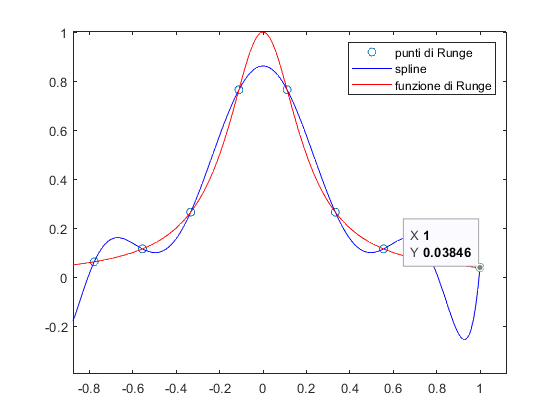

xrun = linspace(-1, 1, 10); % costruisco l'asse per la spline con 4 punti
yrun = 1./(1 + 25.*xrun.^2); % definisco i punti di Runge
xx = -1:0.01:1;
rungeFnc = 1./(1 + 25.*xx.^2); %definisco la funzione di Runge
for i=1:length(xx)
    m=length(xrun)-1;
    coeff = polyfit(xrun,yrun,m); % genero i coefficienti di una curva polinomiale
    t(i) = polyval(coeff,xx(i)); % ottengo una curva polinomiale valutata nei punti xx, 
                                 % con coefficienti ottenuti dall'output di
                                 % polyfit
end
plot(xrun,yrun,'o', xx, t, 'b', xx, rungeFnc, 'r'); % grafico complessivo

legend({'punti di Runge','spline','funzione di Runge'})

Aumentiamo il numero di nodi che vengono considerati e vediamo cosa accade ad esempio alla sola spline not-a-knot

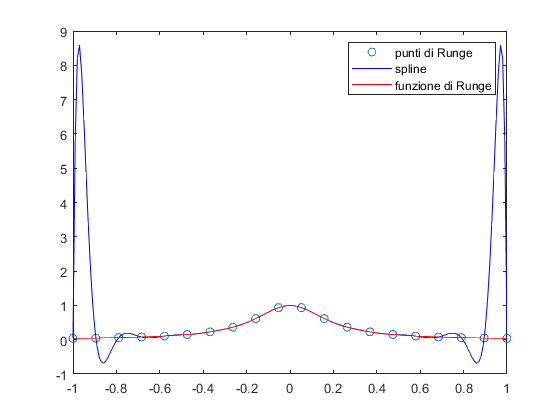

x = linspace(-1, 1, 20); % aumento l'asse x
y = 1./(1 + 25.*x.^2); % definisco i punti di Runge
for i=1:length(xx)
    m=length(x)-1;
    coeff = polyfit(x,y,m);
    t(i) = polyval(coeff,xx(i));
end
plot(x,y,'o', xx, t, 'b-', xx, rungeFnc, 'r'); % grafico complessivo

legend({'punti di Runge','spline','funzione di Runge'})

### Stima dell'errore con la funzione di Runge

Per vedere effettivamente gli effetti del fenomeno, andiamo a fissare un $N\in N$ che sia $\ge 2$, e calcoliamo la funzione spline lineare interpolante *s* della funzione `runge` nei nodi


$$x_k =-5:h_k :5\;,k=0,\ldotp \ldotp \ldotp ,N$$


dove $h_k =10/N$. Ciò che si vuole fare è confrontare il valore della spline con quello della funzione di Runge, ottenuta tramite comando `runge `nei nodi seguenti


$$u_k =-5:h_u :5\;,k=0,\ldotp \ldotp \ldotp ,4N$$


con $h_u =h_k /4$. Per farlo andiamo a valutare l'errore compiuto in norma infinito, utilizzando il comando `norm` apposito. In Matlab:

N = 100; a = -5; b = 5;
hx = (b-a)/N; % calcolo passo di interpolazione
x = a:hx:b; % ascisse interpolate
y = 1./(1+25*x.^2); % funzione di Runge
h1 = hx/4; % passo di test
u = a:h1:b; % ascisse di test
v = interp1(x,y,u,'linear'); % ordinate interpolate di test
vv = 1./(1+25*u.^2); % valore della funzione di Runge nei nodi di test
err = norm(vv-v, 'inf'); % errore calcolato come norma infinito
fprintf('\n \t [ERRORE]: %2.2e', err);


 	 [ERRORE]: 4.12e-02

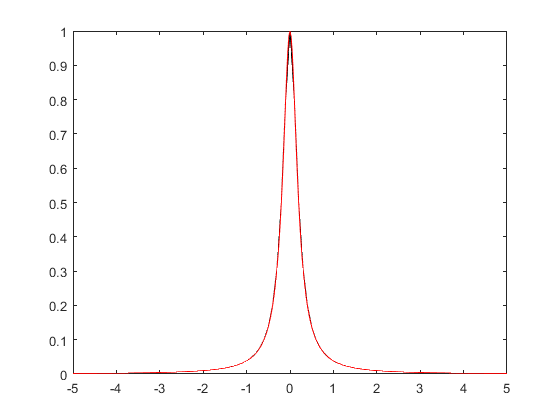

plot(u, v, 'k-', u, vv, 'r-'); % grafico confronto tra spline e runge

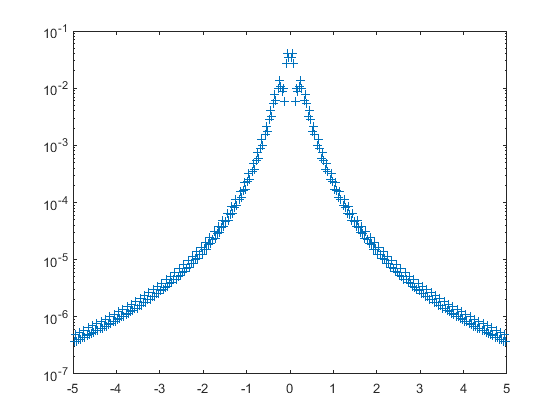

semilogy(u,abs(vv-v), '+'); % grafico dell'errore tra Runge e la funzione interpolata

Come si può vedere, la funzione viene ricostruita così bene che è impossibile distinguere tra funzione spline e funzione di Runge. Nell'intorno dello zero viene raggiunto il massimo dell'errore, che è dell'ordine di ${10}^{-2}$.

Nel caso della funzione di Runge $f$ si ha che la sua derivata seconda ha la seguente espressione:

$f^{\left(2\right)} \left(x\right)=\left(8x^2 \right)/{\left(x^2 +1\right)}^3 -2/{\left(x^2 +1\right)}^2$.

Nel nostro esempio, l'ntervallo ha ampiezza costante, e quindi possiamo dire che $h_i =h$. Quindi, se $x\in \left\lbrack x_i \;,x_{i+1} \right\rbrack$ allora, per la relazione sulla stima dell'errore si ha che


$$\left|f\left(x\right)-s_1 \left(x\right)\right|\le h^2 \frac{M_i }{8}$$


Grafichiamo ora la funzione $f^{\left(2\right)}$ nell'intervallo [-5, 5] e trovato il massimo assoluto, che indichiamo con M, andiamo a verificare che `err` del programma precedente sia effettivamente inferiore alla quantità $h^2 \frac{M_i }{8}$

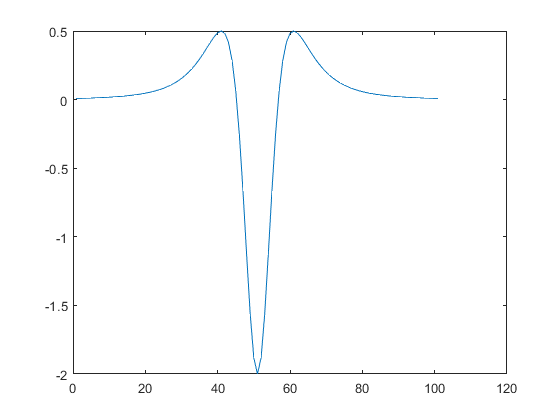

f2 = (8*x.^2)./(x.^2 +1).^3 - 2./(x.^2 + 1).^2; % derivata seconda della funzione f
plot(f2); % grafico della derivata seconda di f

M = max (f2)

M = 0.5000

cost = hx^2*(M/8)

cost = 6.2500e-04

if(err <= cost)
    fprintf('condizione verificata');
else
    fprintf('condizione non verificata');
end

condizione non verificata

La condizione che abbiamo definito, per questo esempio, non è verificata in quanto l'errore che è stato stimato è di circa tre ordini di grandezza maggiore rispetto alla quantità teorica che mi aspettavo. 

## Confronto tra interpolazione lineare e cubica

Andiamo ora a verificare quali sono effettivamente le differenze che sussistono tra una interpolazione di tipo lineare, cioè con una spline di grado 1, e tra una interpolazione effettuata mediante una spline cubica. Prendiamo la funzione $f\left(x\right):=\log \left(x\right)$ definita nell'intervallo $\left\lbrack a,b\right\rbrack :=\left\lbrack 1,2\right\rbrack$, che andiamo a suddividere in *N *subintervalli. Calcoliamo poi, al variare di $N=3\;,4,5,\ldotp \ldotp \ldotp ,10$ le interpolanti splines lineari a tratti, cubici con vincolo *not-a-knot *o *naturali.* Andiamo poi a dare una stima dell'errore di interpolazione. Vediamolo a livello di codice

a = 1; b = 2;
int_type =1; % a seconda del valore impostato di int_type sto generando un tipo di spline

switch int_type
    case 1
        fprintf('\n [spline lineare] \n');
    case 2
        fprintf('\n [spline cubica naturale] \n');
    case 3
        fprintf('\n [spline cubica not a knot] \n');
end


 [spline lineare] 



 [N]:  3 [ERR. (INF)] 1.03e-02

 [EST.][MIN]: 6.94e-03 [MAX]: 2.78e-02

[ok]


 [N]:  4 [ERR. (INF)] 6.21e-03

 [EST.][MIN]: 3.91e-03 [MAX]: 1.56e-02

[ok]


 [N]:  5 [ERR. (INF)] 4.15e-03

 [EST.][MIN]: 2.50e-03 [MAX]: 1.00e-02

[ok]


 [N]:  6 [ERR. (INF)] 2.97e-03

 [EST.][MIN]: 1.74e-03 [MAX]: 6.94e-03

[ok]


 [N]:  7 [ERR. (INF)] 2.23e-03

 [EST.][MIN]: 1.28e-03 [MAX]: 5.10e-03

[ok]


 [N]:  8 [ERR. (INF)] 1.73e-03

 [EST.][MIN]: 9.77e-04 [MAX]: 3.91e-03

[ok]


 [N]:  9 [ERR. (INF)] 1.39e-03

 [EST.][MIN]: 7.72e-04 [MAX]: 3.09e-03

[ok]


 [N]: 10 [ERR. (INF)] 1.14e-03

 [EST.][MIN]: 6.25e-04 [MAX]: 2.50e-03

[ok]

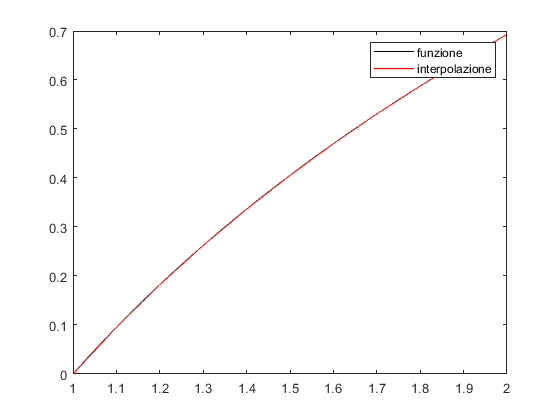


for N=3:10
    h = (b-a)/N;
    x=a:h:b;
    y=log(x);
    s=a:(h/10):b;
    
    switch int_type
        case 1 %CASO DI UNA SPLINE LINEARE
            t=interp1(x,y,s,'linear');
            err(N)=norm(t-log(s),inf);
            err_ext_min=(2/(b^2))*(h^2)/8; % errore sul primo estremo
            err_ext_max=(2/(a^2))*(h^2)/8; % errore sull'ultimo estremo
            fprintf('\n [N]: %2.0f [ERR. (INF)] %2.2e',N, err(N));
            fprintf(' [EST.][MIN]: %2.2e [MAX]: %2.2e',err_ext_min,err_ext_max);
            if( (err(N) > err_ext_min) && (err(N) < err_ext_max))
                fprintf('[ok]');
            else
                fprintf('[not ok]');
            end
        case 2 %CASO DI UNA SPLINE CUBICA NATURALE
            pp1 = csape(x,y,'variational');
            t = ppval(pp1,s);
            err(N)=norm(t-log(s),inf);
            fprintf('\n [N]: %2.0f [ERR. (INF)] %2.2e',N, err(N));
        case 3 %CASO DI UNA SPLINE CUBICA NOT A KNOT
            t = spline(x,y,s);
            err(N)=norm(t-log(s),inf);
            fprintf('\n [N]: %2.0f [ERR. (INF)] %2.2e',N, err(N));
    end
    
    plot(s,log(s), 'k-'); % grafico della funzione logaritmo usata
    hold on;
    plot(s,t,'r-'); % grafico dell'interpolazione effettuata
    pause(1);
    legend({'funzione','interpolazione'})
    hold off;
    
end

Dai risultati ottenuti possiamo vedere che, nel caso di una spline lineare, matematicamente si ottiene che la derivata seconda della funzione $f\left(x\right)=\log \left(x\right)$ è la funzione $f^{\left(2\right)} \left(x\right)=-\frac{1}{x^2 }$ . Dal punto di vista della stima dell'errore, quindi, sapendo che ${\left|f\right.}^{\left(2\right)} \left(x\right)\left|=\left|-\frac{1}{x^2 }\right|=\frac{1}{x^2 }\right.$ , si ottiene che la derivata seconda rispetterà il seguente vincolo:


$$\frac{1}{b^2 }<\left|f^{\left(2\right)} \left(\xi \right)\right|<\frac{1}{a^2 }$$


per qualsiasi valore di $\xi$ nell'intervallo $\left(a\ldotp b\right)$. Ciò è intuibile facilmente osservando che la funzione $f^{\left(2\right)}$ è una funzione decrescente.

### Approssimazione di una curva parametrica

Proviamo ora ad effettuare una approssimazione tramite le spline di una curva parametrizzata. In generale, presa una curva, rappresentata da una funzione $f:\left\lbrack a,b\right\rbrack \to R^2$ del tipo


$$f\left(t\right)=\left(\begin{array}{c}
u\left(t\right)\\
v\left(t\right)
\end{array}\right)$$


con $u,v\;:\left\lbrack a,b\right\rbrack \to R^{\;}$. Noti i valori $u\left(t_i \right),v\left(t_i \right)$per $i=0,1,\ldotp \ldotp \ldotp ,N$, ciò che si può fare è approssimare la curva $f\left(t\right)$ usando le spline calcolate partendo dalle funzioni $u$ e $v$. Indicando con $s_u \;$e con $s_v$ le spline relative alle due funzioni, si va a costruire una interpolazione $\bar{f}$ che approssima la funzione $f$, dove


$$\bar{f} \left(t\right)=\left(\begin{array}{c}
s_u \left(t\right)\\
s_v \left(t\right)
\end{array}\right)$$


Un classico esempio di approssimazione che è possibile studiare è utilizzando la funzione parametrica del cerchio. Essendo l'equazione del cerchio


$$f\left(t\right)=\left(\begin{array}{c}
\cos \left(t\right)\\
\textrm{sen}\left(t\right)
\end{array}\right)$$


per $t=\left\lbrack 0,2\pi \right\rbrack$. Se pongo

$t_k =2k\frac{\pi }{N}\;,k=0,\ldotp \ldotp \ldotp ,N$,

posso facilmente calcolare l'approssimante spline tramite il comando `interp1` applicato alla coppia `t,u `e `t,v` dove `t `sarà il vettore campionato con i valori di $t_k$, così come $u=\left(u\left(t_k \right)\right)$e  $v=\;\left(v\left(t_k \right)\right)$. Andiamo a vederlo nella pratica

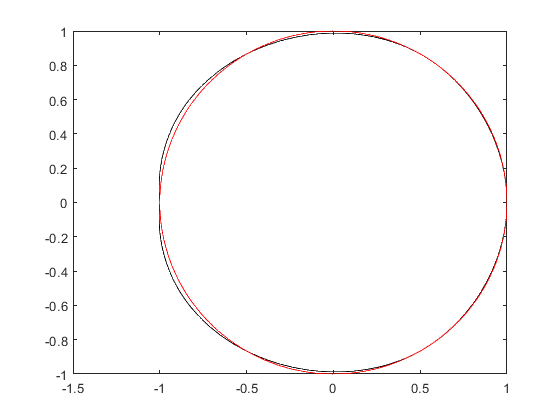

N = 6; % per l'esempio utilizziamo un N pari a 6
a= -pi; b= pi;  % consideriamo l'intervallo [-pi; pi]
h=(b-a)/N; % parametri per la discretizzazione dell'intervallo

% PUNTI DI INTERPOLAZIONE
t = a:h:b;      % punti della curva
xt = cos(t);    % ascissa del punto della curva
yt = sin(t);    % ordinata del punto della curva

% PUNTI DI TEST
htest = h/100;      % passo del parametro t
ttest = a:htest:b;  % parametri della curva di test

% CALCOLO SPLINES DELLA CURVA PARAMETRICA
xttest = interp1(t,xt,ttest,'spline');
yttest=interp1(t,yt,ttest,'spline');

% GRAFICO
theta=0:htest:2*pi;
plot(xttest,yttest,'k-',cos(theta),sin(theta),'r-');

Si può notare che la parte grafica di Matlab, in particolare la funzione `plot`, tende ad *ovalizzare* la funzione in ingresso quando si utilizza un N più elevato, come avviene in questo caso, con N pari ad 8. 

## Le spline in Matlab

La routine di Matlab per il calcolo di una curva spline cubica, come abbiamo visto, è il comando `spline`. 

Infatti, considerato x le ascisse dei punti da interpolare, y le ordinate, e xx un certo vettore di ascisse in cui voglio valutare la spline interpolante, il comando `spline(x,y,xx) `restituisce i valori della spline cubica interpolante nei punti indicati con il vettore xx, calcolata con le condizioni agli estremi di default, cioè utilizzando la condizione **not-a-knot**, che permette di imporre una continuità anche della derivata terza nel secondo e nel penultimo nodo che sto considerando. 

### PPform di una spline

Un altro modo per ottenere le informazioni di una spline, è utilizzando la sua forma PP, detta **PPform **(*piecewise polynomial form*).

La PPform di una spline è in grado di ottenere i vari "pezzi" dei polinomi componenti la spline, e ciò è utile in quanto è poi possibile manipolare le informazioni polinomiali che ottengo calcolando derivate, integrali ecc. Andiamo allora a calcolare una PPform tramite comando apposito, e generare una spline partendo dalla sua PPform

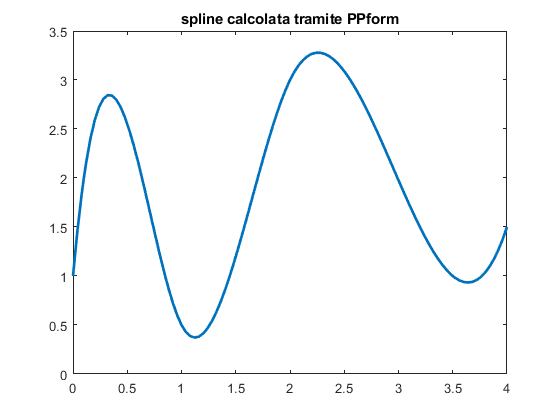

x = [0 0.1 1 2 3.5 4];
y = [1 2 0.5 3 1 1.5];
PP = csapi(x,y);
dpp = fnder(PP); % calcolo la derivata della PPform
fnplt(PP) % è indifferente usare fnplt o il comando plot

title('spline calcolata tramite PPform')

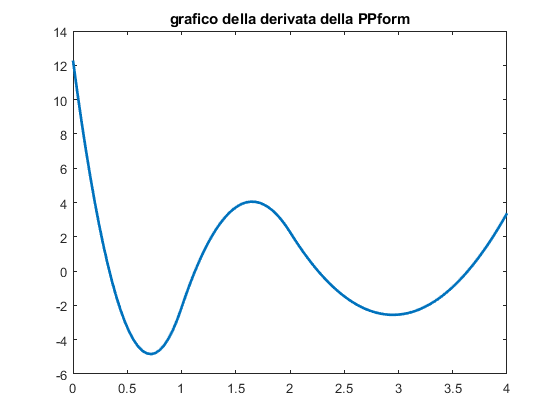

fnplt(dpp) % grafico della derivata della spline, che è ancora una PPform

title('grafico della derivata della PPform')

Come si può vedere, la spline ottenuta tramite `fnplt` è identica a quella generata tramite il comando `spline`, ma la PPform permette di andare a calcolare anche informazioni aggiuntive, come detto, ad esempio per la derivata, rappresentata in questo caso con la variabile `dpp`.

Vediamo un esempio di derivata di una spline, valutando l'errore commesso su essa

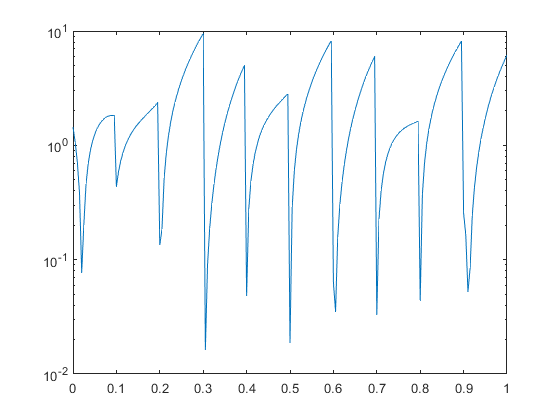

a=0; b=1; % considero l'intervallo [0,1]

% INTERPOLAZIONE CON LE SPLINE
h = (b-a)/10; % usiamo un N paria 10
x = a:h:b; % discretizzo l'asse x
y = sin(10*x); % y rappresenta la nostra funzione
ppForm = spline(x,y); % calcolo la spline
[breaks, coeffs] = unmkpp(ppForm); % estraggo le informazioni dalla ppform della spline

% DERIVATA DELLA SPLINE
N = size(coeffs, 1);  % definisco N
dcoeffs = [zeros(N,1) 3*coeffs(:,2) coeffs(:,3)]; % definisco i coefficienti della ppform della derivata
ppForm1 = mkpp(breaks, dcoeffs); % creo la pp form della derivata della spline
u= a:0.005:b;
dsu = ppval(ppForm1, u); % calcolo derivata della spline tramite ppform
dfu = 10*cos(10*u); % calcolo della derivata classica della funzione

% GRAFICO ERRORE ASSOLUTO
semilogy(u, abs(dsu-dfu), '-');

### Spline tramite comando `csape`

Per ottenere una spline cubica interpolante è possibile anche utilizzare un comando differente da quelli visti in precedenza, che permette di specificare anche delle condizioni agli estremi dell'intervallo differenti da quelle di default. Vediamo alcuni esempi:

pp = csape (x, y, 'v');

Il qualificatore **'v'** permette di definire una spline che sia di tipo naturale.

pp = csape(x, y, 'p');

Il qualificatore **'p'** permette di generare una spline di tipo periodica.

%pp = csape(x, [y'(a) y y'(b)], 'clamped');

Il qualificatore **'clamped'** , a differenza degli altri, ha bisogno che in input alla funzione `csape` vengano dati anche i valori della derivata della funzione negli estremi dell'intervallo. Infatti, ciò va a generare una spline completa, detta anche vincolata.

pp = csape(x, y, 'not-a-knot');

Il qualificatore **'not-a-knot'**, come è facile intuire, restituisce une spline di tipo not-a-knot. Questo qualificatore è quello che la funzione utilizza di default se non ne viene specificato uno in particolare.

## Coronavirus: elaborazione dati e approssimazione

### Ottenimento informazioni sui contagi

Un particolare set di dati da analizzare, specialmente nel periodo in cui ci troviamo, è quello relativo ai contagi nazionali da SARS-CoV-2, comunemente conosciuto come **coronavirus** o anche Covid-19. Per effettuare l'analisi sui dati, è importante reperire i dati stessi; in particolare, in Italia quest'ultimi sono messi a disposizione dal ministero tramite il portale apposito del DPC (*Dipartimento della Protezione Civile*). Una volta ottenuti i file necessari e aggiornati, è possibile importare le informazioni dai file csv tramite l'**Import tool** di Matlab, che permette di aprire il fil ecsv e di selezionare il set di dati che si vuole importare nel workspace che si sta utilizzando, o più facilmente utilizzando i seguenti comandi per l'importazione:

% SETUP DELLE OPZIONI DI IMPORTAZIONE DEI DATI
opts = delimitedTextImportOptions("NumVariables", 16);

% SPECIFICA RANGE E CARATTERE DELIMITATORE
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% DEFINIZIONE DELLE VARIABILI E DEI TIPI
opts.VariableNames = ["data", "stato", "ricoverati_con_sintomi", "terapia_intensiva", "totale_ospedalizzati", "isolamento_domiciliare", "totale_positivi", "variazione_totale_positivi", "nuovi_positivi", "dimessi_guariti", "deceduti", "totale_casi", "tamponi", "casi_testati", "note_it", "note_en"];
opts.VariableTypes = ["datetime", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% DEFINIZIONE DELLE PROPRIETA' DEL FILE
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% SPECIFICA DELLE PROPRIETà DELLE VARIABILI
opts = setvaropts(opts, "stato", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "data", "InputFormat", "yyyy-MM-dd");
opts = setvaropts(opts, ["note_it", "note_en"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["note_it", "note_en"], "ThousandsSeparator", ",");

% IMPORTAZIONE DATI
TabellaDatiCovid = readtable('Dati CoronaVirus/COVID-19-master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv',opts);

% CLEAR DELLA VARIABILE TEMPORANEA PER LE OPZIONI
clear opts;

Tramite questi comandi siamo in grado di recuperare l'intero set di dati contenuto nel file che si va ad indicare.

Il set di dati va ad inserirsi nella variabile `TabellaDatiCovid`. Sfruttando la tabella creata, è possibile visualizzare i dati in forma matriciale. Se, ad esempio, sono interessato alle prime 5 righe e le prime 5 colonne, posso sfruttare i classici comandi di elaborazione delle tabelle, simili a quelli per le matrici su Matlab, per visualizzare dati parziali della tabella stessa:

TabellaDatiCovid(1:5,1:5)

ans = 5×5 table
       data       stato    ricoverati_con_sintomi    terapia_intensiva    totale_ospedalizzati
    __________    _____    ______________________    _________________    ____________________

    2020-02-24     ITA              101                     26                    127         
    2020-02-25     ITA              114                     35                    150         
    2020-02-26     ITA              128                     36                    164         
    2020-02-27     ITA              248                     56                    304         
    2020-02-28     ITA              345                     64                    409         


### Visualizzazione dei grafici sui dati nazionali

Una volta effettuato il recupero dei dati sui contagi dall'apposito set della Protezione Civile, è possibile ricreare dei grafici dell'andamento generale dei contagi, così come è possibile studiare una eventuale crescita del numero di contagiati, di ricoverati, e settorializzare i dati per regione. In particolare, per l'ultimo aspetto, la Protezione Civile mette a disposizione ulteriori file, riguardandi l'andamento dei contagi regione per regione. Andiamo a rappresentare graficamente i contagi dall'inizio dell'epidemia alla data odierna, 8 Giugno 2020. Graficiamo ad esempio, il numero totale dei positivi

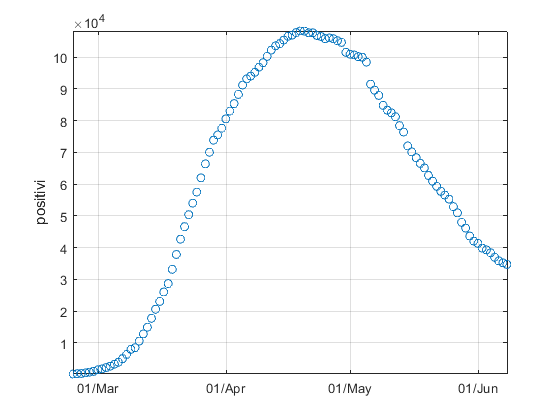

NumPosArray = table2array(TabellaDatiCovid(:,7)); % converto i dati in un array
DateArray = datenum(TabellaDatiCovid.data); % converto le date in valori numerici
plot(DateArray, NumPosArray, 'o')
grid;
datetick('x', 'dd/mmm', 'keeplimits');
axis tight;
ylabel('positivi');

Oltre a fare ciò, sarebbe interessante andare a vedere come si comportano i dati se trasportati in un diagramma logaritmico, per cercare di stabilite in quanto tempo quindi la curva sarà estinta del tutto se il trend rimarrà lo stesso. Rappresentiamo quindi i dati con un diagramma semilogaritmico

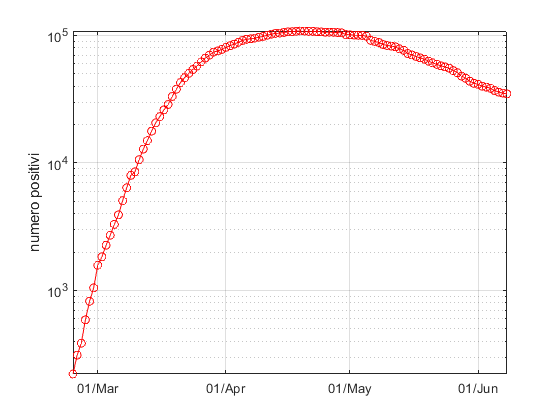

semilogy(DateArray, NumPosArray, '-o red')
grid;
datetick('x', 'dd/mmm', 'keeplimits');
axis tight;
ylabel('numero positivi');

Quello che si vede è che nel primo periodo sembrerebbe che l'andamento sia stato di tipo esponenziale, dal momento che il grafico semilogaritmico presenta un tratto pressocchè rettilineo. A partire dal mese di marzo, mese in cui sono stati presi i primi provvedimenti e attuate le prime misure di contenimento, istanziando le prime zone rosse in Italia, la pendenza del grafico sembra diminiure, e ciò ha portato a sperare che ci fossimo avvicinati alla zona di flesso del grafico epidemiologico. Infatti, in analisi medica, l'andamento di una epidemia è quasi sempre esponenziale nel primo periodo, raggiunge un picco e l'andamento diventa di tipo gaussiano. 

Volendo fare un analisi più accurata, andiamo a considerare il numero totale di casi registrati, e grafichiamone l'andamento allo stesso modo

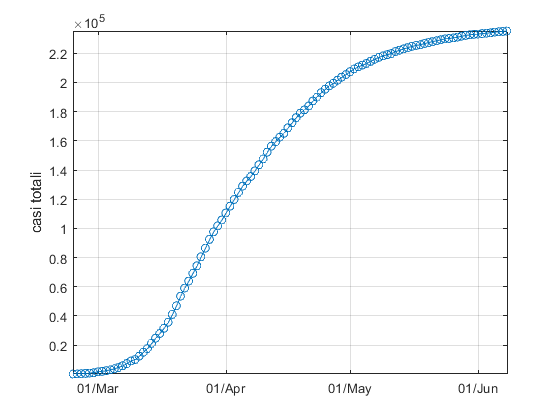

NumCasiTotArray = table2array(TabellaDatiCovid(:,12)); % converto i dati in un array
plot(DateArray, NumCasiTotArray, '-o')
grid;
datetick('x', 'dd/mmm', 'keeplimits');
axis tight;
ylabel('casi totali');

Il numero di positivi deriva dal numero di tamponi effettuato, quindi, per un analisi più accurata, è fondamentale sapere come vengono raccolti ed analizzati i tamponi stessi. All'inizio i tamponi venivano raccolti per tutte le persone che venivano in contatto con soggetti che avevano sviluppato dei sintomi, e che quindi potevano essere riconosciuti come malati di coronavirus, mentre successivamente la strategia di raccolta è stata modificata: si è deciso quindi di effettuare i tamponi solo ai soggetti che presentavano dei sintomi. Ciò quindi comporta che i cosidetti pazienti **asintomatici**, a partite da un certo momento, che corrisponde alla fine del mese di febbraio circa, non siano più stati conteggiati. Questo fa si che ci siano state persone che sono risultate contegiate dal virus ma che siano guarite autonomamente. Da questo punto di vista quindi, il dato dei casi totali, così come il dato sui positivi, non è particolarmente affidabile.

Tra tutti i dati raccolti, triste dirlo, ma quello più affidabile è quello riguardante le morti, che ci aiuta ad analizzare l'andamento esponenziale della curva in modo sicuramente più fedele. Per rendere il tutto più pulito a livello di codice, definiamo una function, che chiamo `plotnatlog`, per graficare i dati sia in scala naturale che in scala logaritmica.

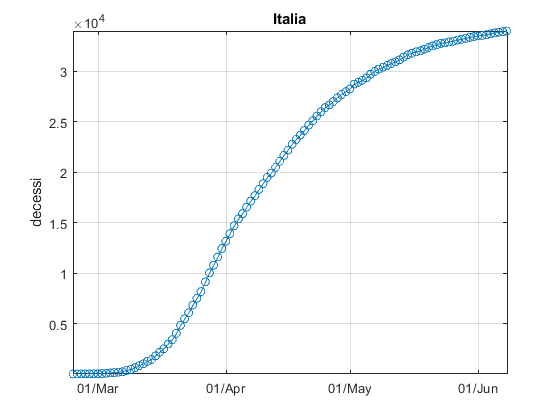

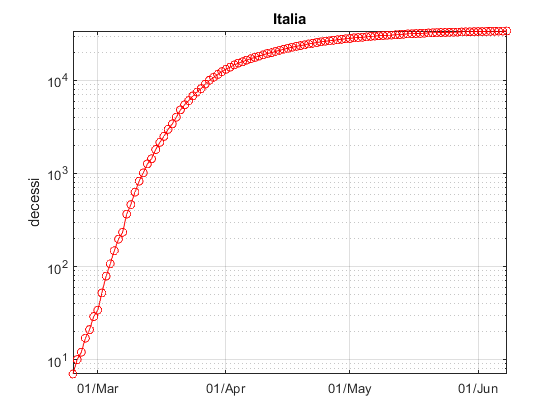

NumDecArray = table2array(TabellaDatiCovid(:,11)); % converto i dati in un array
etichettay = 'decessi';
titolo = 'Italia';
plotnatlog(DateArray,NumDecArray, etichettay, titolo);

Come è possibile vedere dai grafici dei decessi, la crescita sembra essere puramente esponenziale per il primo tratto, per poi quasi stabilizzarsi su un valore. L'ultimo tratto evidenzia quindi una frenata dell'andamento esponenziale, dal momeno che il grafico semilogaritmico sembra tendere ad un valore limite.

### Visualizzazione dei grafici sui dati regionali

Interessante è vedere l'andamento dei dati tra le varie regioni, prendendo in esame alcune tra le regioni più colpite come la Lombardia, e confrontarle con una regione meno colpita come la Campania. 

Per farlo dobbiamo andare a raccogliere i dati regione per regione, e quindi dobbiamo utilizzare un altro file, messo a disposizione della protezione civile. Utilizziamo quindi lo stesso codice usato in precedenza, andando però a pescare su un file differente, e raccogliendo il tutto in una variabile singola per tutte le regioni.

% SETUP DELLE OPZIONI DI IMPORTAZIONE DEI DATI
opts = delimitedTextImportOptions("NumVariables", 21);

% SPECIFICA RANGE E CARATTERE DELIMITATORE
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% DEFINIZIONE DELLE VARIABILI E DEI TIPI
opts.VariableNames = ["data", "Var2", "stato", "codice_regione", "denominazione_regione", "lat", "long", "ricoverati_con_sintomi", "terapia_intensiva", "totale_ospedalizzati", "isolamento_domiciliare", "totale_positivi", "variazione_totale_positivi", "nuovi_positivi", "dimessi_guariti", "deceduti", "totale_casi", "tamponi", "casi_testati", "Var20", "Var21"];
opts.SelectedVariableNames = ["data", "stato", "codice_regione", "denominazione_regione", "lat", "long", "ricoverati_con_sintomi", "terapia_intensiva", "totale_ospedalizzati", "isolamento_domiciliare", "totale_positivi", "variazione_totale_positivi", "nuovi_positivi", "dimessi_guariti", "deceduti", "totale_casi", "tamponi", "casi_testati"];
opts.VariableTypes = ["datetime", "string", "categorical", "double", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string", "string", "string"];

% DEFINIZIONE DELLE PROPRIETA' DEL FILE
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% SPECIFICA DELLE PROPRIETà DELLE VARIABILI
opts = setvaropts(opts, ["Var2", "casi_testati", "Var20", "Var21"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "stato", "denominazione_regione", "lat", "long", "casi_testati", "Var20", "Var21"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "data", "InputFormat", "yyyy-MM-dd");

% IMPORTAZIONE DATI
TabellaDatiCovidRegioni = readtable('Dati CoronaVirus/COVID-19-master/dati-regioni/dpc-covid19-ita-regioni.csv',opts);

% CLEAR DELLA VARIABILE TEMPORANEA PER LE OPZIONI
clear opts;

Come possiamo vedere studiando meglio la tabella, questa presenta delle diciture aggiutive rispetto a quella nazionale, come il nome della regione, il rispettivo identificativo progressivo, e le coordinate della regione stessa.

TabellaDatiCovidRegioni(1:7,1:7)

ans = 7×7 table
       data       stato    codice_regione    denominazione_regione         lat             long         ricoverati_con_sintomi
    __________    _____    ______________    _____________________    _____________    _____________    ______________________

    2020-02-24     ITA           13          Abruzzo                  4.235.122.196    1.339.843.823               0          
    2020-02-24     ITA           17          Basilicata               4.063.947.052    1.580.514.834               0          
    2020-02-24     ITA           21          P.A. Bolzano             4.649.933.453    1.135.662.422               0          
    2020-02-24     ITA           18          Calabria                 3.890.597.598    1.659.440.194          

Fatto ciò, vado a creare due tabelle separate per Lombardia e Campania, filtrando i dati dalla tabella delle regioni sfruttando il campo `denominazione_regione`. Avremmo potuto sfruttare anche il codice della regione, ma sarebbe stato troppo oneroso spulciare la tabella per reperire i codici.

TabellaCampania = TabellaDatiCovidRegioni(TabellaDatiCovidRegioni.denominazione_regione == 'Campania', :);
TabellaLombardia = TabellaDatiCovidRegioni(TabellaDatiCovidRegioni.denominazione_regione == 'Lombardia', :);

Come prima analisi andiamo a costruire gli stessi grafici fatti per i dati nazionali, sul numero di positivi, sul totale dei casi e sulle morti per le due regioni che stiamo considerando. Per prima cosa definiamo un asse temporale anche per le regioni, e sfruttiamo la function creata per graficare gli andamenti.

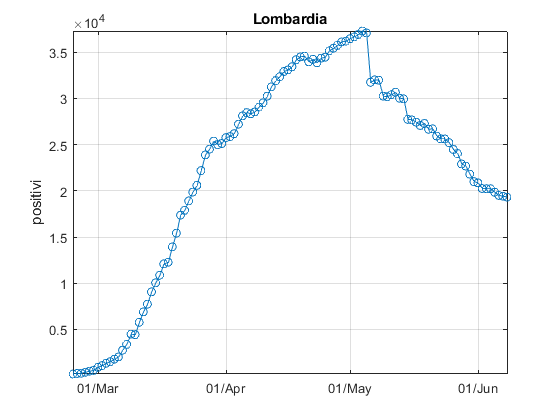

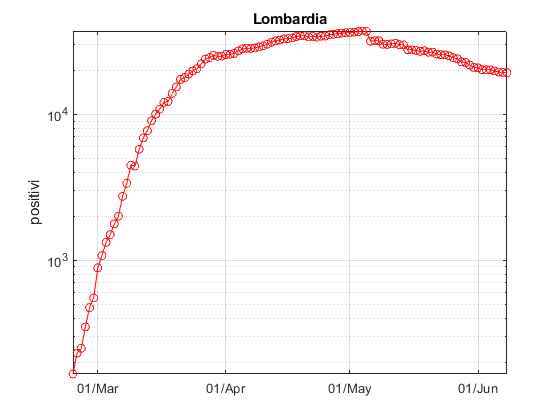

% definisco due array, anche se non serve visto che i dati sono stati
% raccolti usando lo stesso asse temporale
DateArrayLombardia = datenum(TabellaLombardia.data); % definizione array delle date in Lombardia
DateArrayCampania = datenum(TabellaCampania.data); % definizione array delle date in Campania

plotnatlog(DateArrayLombardia, TabellaLombardia.totale_positivi, 'positivi', 'Lombardia') % andamento positivi in Lombardia

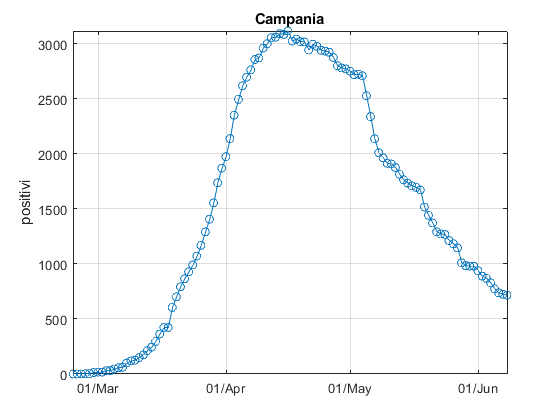

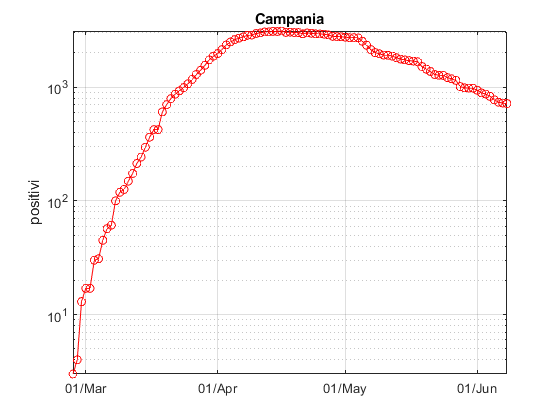

plotnatlog(DateArrayCampania, TabellaCampania.totale_positivi, 'positivi', 'Campania') % andamento positivi in Campania

Come visto per i dati relativi all'intera nazione, il dato dei positivi nasconde alcune incoerenze, che si riflettono su una scarsa affidabilità dei dati stessi. Infatti, come si può vedere, la crescita iniziale per entrambe le regioni, anche se sembra essere esponenziale, in realtà non lo è. Ciò che si può però registrare, analizzando le differenze tra i due grafici, è che, come ormai sappiamo, la regione Lombardia risulta sicuramente la più colpita: infatti, il picco di positivi raggiunti è decisamente più alto. Un dato però preoccupante è che, se in Campania l'andamento della discesa sembra avere una "velocità" pressocchè simile a quella assunta dal grafico nella fase di crescita iniziale, in Lombardia la curva sembra procedere in discesa con una velocità sicuramente minore. 

Per farci un idea più precisa, andiamo a graficare le morti per le due regioni:

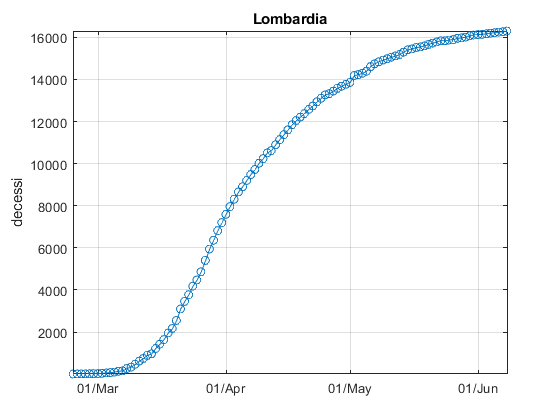

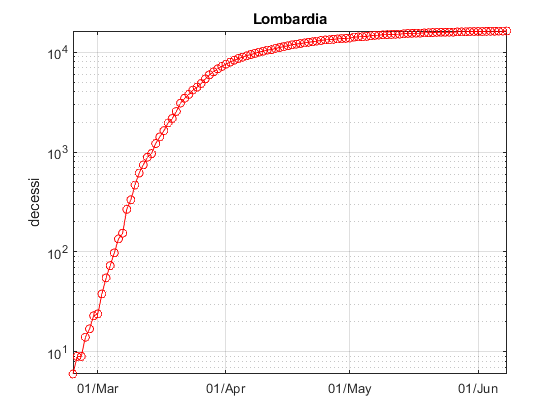

plotnatlog(DateArrayLombardia, TabellaLombardia.deceduti, 'decessi', 'Lombardia') % andamento decessi in Lombardia

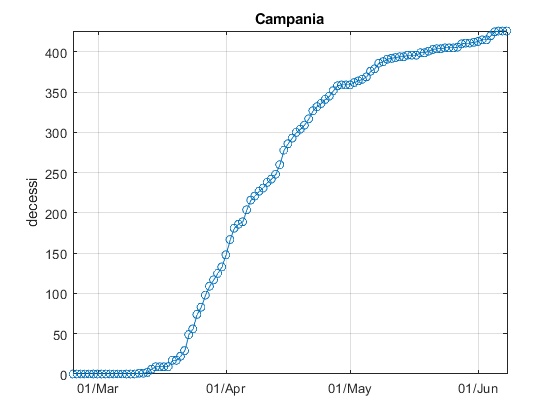

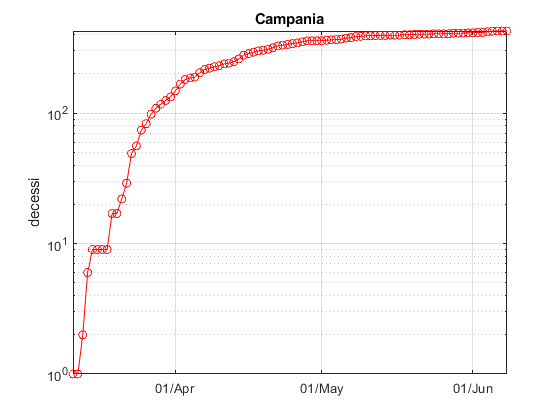

plotnatlog(DateArrayCampania, TabellaCampania.deceduti, 'decessi', 'Campania') % andamento decessi in Campania

Come si vede, la curva campana riguardante i decessi è decisamente più irregolare di quella lombarda, il che denota che la crescita dei decessi nella regione Lombardia ha avuto un andamento decisamente più esponenziale rispetto a quella calcolata con i dati della regione Campania. Inoltre, è possibile vedere che i dati campani acquistano rilevanza solo a partire da metà marzo, a conferma del fatto che l'epidemia si sia diffusa prima in Lombardia per poi espandersi in tutt'Italia, e quindi in Campania.

### Modello di previsione dei dati nazionali

In una prima analisi predittiva, quello che possiamo fare è  andare eventualmente a creare una spline interpolante che segue l'andamento dei dati nazionali, utilizzando il codice seguente

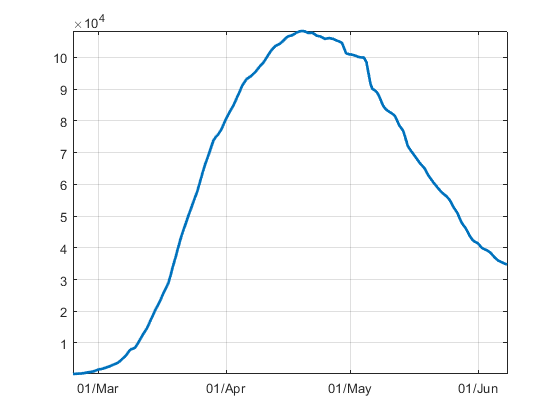

yContagi = spline (datenum(TabellaDatiCovid.data), NumPosArray); % genero una spline interpolante sui dati dei positivi italiani
fnplt(yContagi);
datetick('x', 'dd/mmm', 'keeplimits');
grid;
axis tight;

Interpolare però i dati nazionali non ci da una vera e propria informazione aggiuntiva riguardo l'andamento dei dati, e non si riesce ad ottenere un modello sui dati che riesca a fare una stima dell'andamento futuro della curva. Per creare un modello sui dati che riesca a fare ciò ho bisogno di utilizzare la funzione `regress` di Matlab. Per capire perchè questa può essere utile, andiamo a visualizzarne l'help:

help regress

 regress Multiple linear regression using least squares.
    B = regress(Y,X) returns the vector B of regression coefficients in the
    linear model Y = X*B.  X is an n-by-p design matrix, with rows
    corresponding to observations and columns to predictor variables.  Y is
    an n-by-1 vector of response observations.
 
    [B,BINT] = regress(Y,X) returns a matrix BINT of 95% confidence
    intervals for B.
 
    [B,BINT,R] = regress(Y,X) returns a vector R of residuals.
 
    [B,BINT,R,RINT] = regress(Y,X) returns a matrix RINT of intervals that
    can be used to diagnose outliers.  If RINT(i,:) does not contain zero,
    then the i-th residual is larger than would be expected, at the 5%
    significance level.  This is evidence that the I-th observation is an
    outlier.
 
    [B,BINT,R,RINT,STATS] = regress(Y,X) returns a vector STATS containing, in
    the following order, the

Come è possibile leggere tra le righe dell'help di questa function, la funzione crea una regressione lineare, cioè un modello lineare dei dati in ingresso, sfruttando la tecnica dei minimi quadrati. Per prima cosa andiamo a definire delle variabili che ci serviranno per creare tramite la funzione il modello dei dati: in particolare, andiamo a creare la matrice che nell'help viene indicata con X. Questa è composta da una colonna di 1, e le colonne successive devono essere proporzionali al tempo $t$ , al tempo $t^2$, e così via. Nel nostro caso, siccome vogliamo un modello lineare, la X sarà composta da 5 colonne, perchè maggiore è la potenza della variabile temporale, migliore sarà l'apprissimazione sui dati. D'altro canto, però, aumentando il numero di colonne della matrice si corre il rischio di individuare un modello che non ci da informazioni abbastanza veritiere a lungo termine. Definiamo quindi X, e calcoliamo il modello dei dati

xt = DateArray - DateArray(1) + 1; % xt conta il numero di giorni in un certo senso
% xt serve a scalare meglio la matrice X

X = [ones(size(DateArray)) xt xt.^2 xt.^3 xt.^4]; % matrice 
[B,BINT,R,RINT] = regress(log(NumPosArray),X); % calcolo il modello partendo dai dati logaritmici
% La matrice X con gli elementi alla 4^a potenza è un buon compromesso per
% l'affidabilità del modello che otteniamo

yhat = X*B; % calcolo dei valori di previsione del modello; B è il vettore dei parametri del modello
NumPosArrayhat = exp(yhat); % valori non logaritmici

A questo punto possiamo andare a ricreare il grafico dei positivi in italia e grafichiamo il modello di confronto

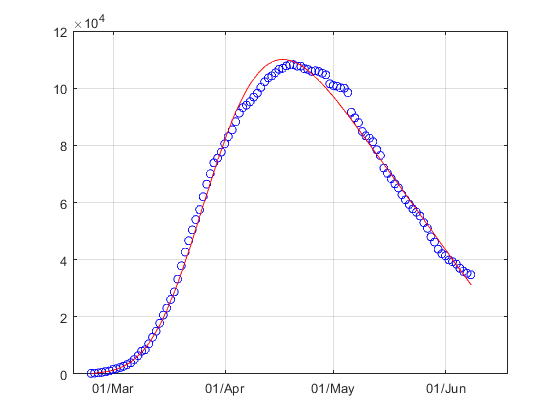

plot(DateArray, NumPosArray, 'o blue');
hold on;
plot(DateArray, NumPosArrayhat, '-r');
datetick('x', 'dd/mmm', 'keeplimits');
grid;
hold off;

Ora, per stabilire una previsione sul futuro della curva dei contagi è andare ad allungare il vettore dei tempi e vedere il modello che andamento presenta. Per fare ciò costruiamo un vettore dei tempi più lungo di qualche settimana e vediamo come potrebbe essere la curva. Ad esempio, andiamo avanti fino al 15 Luglio

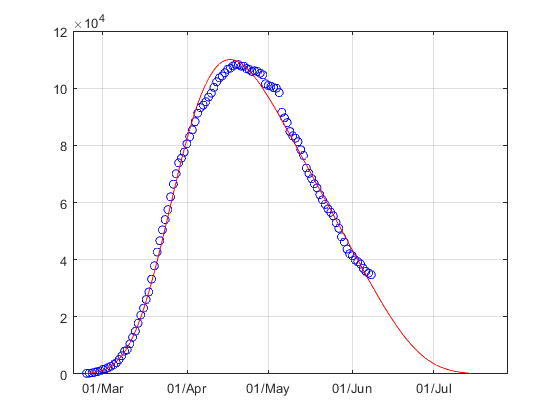

firstday = datenum(2020,02,23);
lastday = datenum(2020,07,15);
DateAllungate = [firstday+1:lastday]';
xthat = DateAllungate - firstday;
Xhat = [ones(size(DateAllungate)) xthat xthat.^2 xthat.^3 xthat.^4];

yhat = Xhat*B; % calcolo dei valori di previsione del modello; B è il vettore dei parametri del modello
NumPosArrayhat = exp(yhat);

% Grafici
plot(DateArray, NumPosArray, 'o blue');
hold on;
plot(DateAllungate, NumPosArrayhat, '-r');
datetick('x', 'dd/mmm', 'keeplimits');
grid;
hold off;

## Conclusioni

L'utilizzo di interpolazioni è sempre più utilizzato in questo periodo, così come negli ambiti più disparati, dal meteo per effettuare previsioni, al trading per graficare dei trend partendo dai dati in cui siamo in possesso. Spesso però si crede che una previsione di tipo matematico sia, in quanto tale, qualcosa che si può ritenere esatto, quando in realtà, nascendo da una approssimazione di rilevamenti scientifici non sempre fedeli e privi di alcun errore, ci si trova invece di fronte a qualcosa che può solo dare un idea di ciò che potrebbe succedere.

Nel caso del coronavirus, i dati raccolti, come abbiamo visto, soffro già di alcuni errori riguardo le metodologie di racoclta degli stessi, e la previsione può senza dubbio essere tutto fuorchè affidabile, ma una scienza come la matematica può dare spunto per alcune previsioni e può mettere in luce difetti sui dati che non si è quasi mai in grado di riscontrare senza aver elaborato i dati stessi.

I dati che sono stati utilizzati hanno riscontrato alcune note positive, e altre purtroppo ancora negative, ma ciò non deve smettere di far sperare chi ancora lotta per trovare una cura, chi ancora lotta per la cura degli ancora numerosi contagiati, e chi come noi tutti, nel nostro piccolo, sta facendo di tutto per evitare che quest'inferno sia arrivato finalmente all'ultimo canto, e spera che tutti insieme potremmo un giorno uscire con serenità, e come diceva Dante, "rimirar le stelle".

## Funzioni utilizzate

### `plotnatlog`

function plotnatlog(t,y, etichettay, titolo)

% DESCRIPTION
% plotting a dataset y using the time axis t
% in natural and semilog scale, using the figure f
% IN:   t = time axis
%       y = data
%       etichettay = name of the y-axis
%       titolo = title of the plots
% OUT:  two subplots in one figure

figure;
plot(t,y, '-o');
datetick('x', 'dd/mmm', 'keeplimits');
axis tight;
grid;
ylabel(etichettay);
title(titolo);

figure;
semilogy(t,y,'-o red');
datetick('x', 'dd/mmm', 'keeplimits');
axis tight;
grid;
ylabel(etichettay);
title(titolo);

end